First we define a triangular matrix with known eigenvalues and a random vector $\mathbf{b}$.

lambda = 10 + (1:100);
A = diag(lambda) + triu(rand(100),1); 
b = rand(100,1);

Next we build up the first ten Krylov matrices iteratively, using renormalization after each matrix-vector multiplication. 

Km = b;
for m = 1:29      
    v = A*Km(:,m);
    Km(:,m+1) = v/norm(v);
end

Now we solve a least squares problem for Krylov matrices of increasing dimension.

warning off    % ignore this line
resid = zeros(30,1);
for m = 1:30  
    z = (A*Km(:,1:m))\b;
    x = Km(:,1:m)*z;
    resid(m) = norm(b-A*x);
end

The linear system approximations show smooth linear convergence at first, but the convergence stagnates after only a few digits have been found.

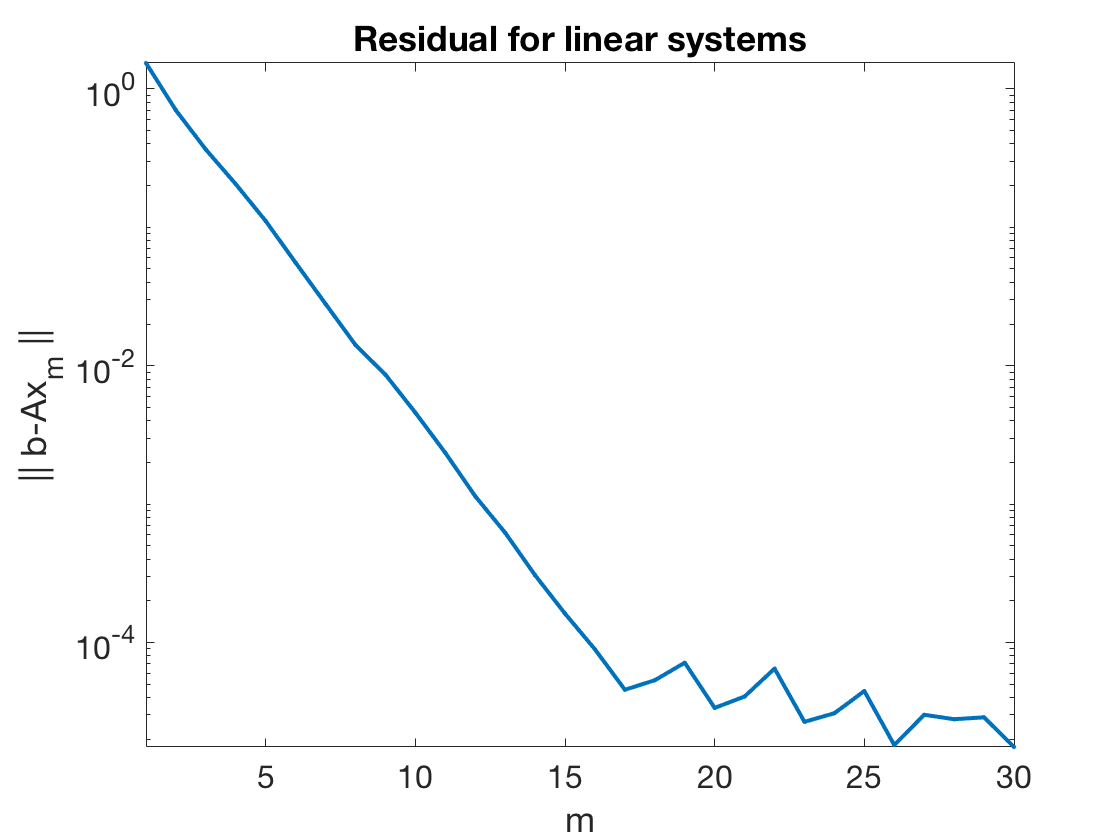

semilogy(resid,'.-')
xlabel('m'), ylabel('|| b-Ax_m ||'), set(gca,'ytick',10.^(-6:2:0))   % ignore this line
axis tight, title('Residual for linear systems')   % ignore this line